# Simulation Of Ground Acceleration Record

Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

%frequency vector
f = linspace(0,48,4096);

- select `bandwidth of the earthquake excitation`

zeta = 0.3;

- select the standard deviation of `earthquake excitation`

sigma = 0.35;

- select `dominant frequency of the earthquake excitation (Hz).`

fn = 10;

- select `value of the envelop function at 90 percent of the duration.`

T90 = 0.25;

- select `normalized duration time when ground motion achieves peak.`

eps = 0.4;

- **select **duration of ground motion;

tn = 60;

Calling this function

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

### Plot Function

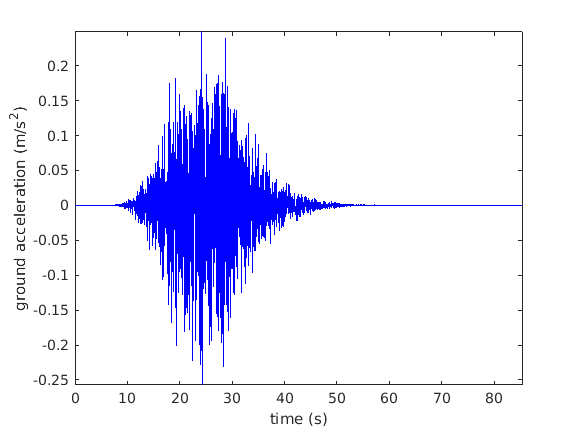

plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

Earthquake data has been generated.

# Earthquake Analysis

**Load Earthquake Data**

**the data is already generated into the workspace**

% plot signal on new figure
figure,plot(t,y)
xlabel('time'),ylabel('signal')

since the data we got is already multiplied with g hence we need not to multiply it again with g(already scalled data)

**Select Subset of Data for Exploration**

We are interested in the time region where the amplitude of the shockwave starts to increase from near zero to maximum levels. Visual inspection of the above plot shows that the time interval from 10 to 25 seconds is of interest. For better visualization we draw black lines at the selected time spots to draw attention to that interval. All subsequent calculations will involve this interval.

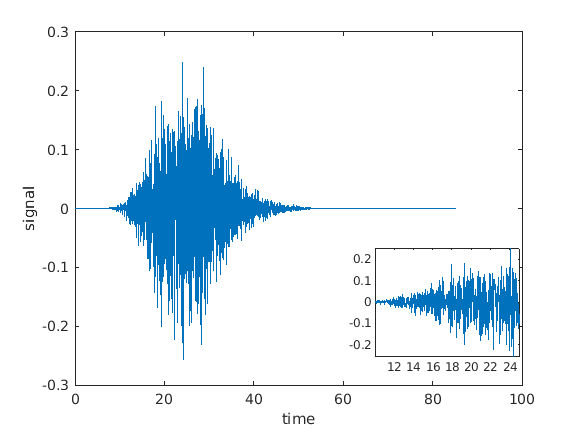

% create a new pair of axes inside current figure
axes('position',[.65 .175 .25 .25])
box on % put box around new pair of axes
indexOfInterest = (t < 25 & (t > 10)); % range of t near perturbation
plot(t(indexOfInterest),y(indexOfInterest)) % plot on new axes
axis tight

let's see this 

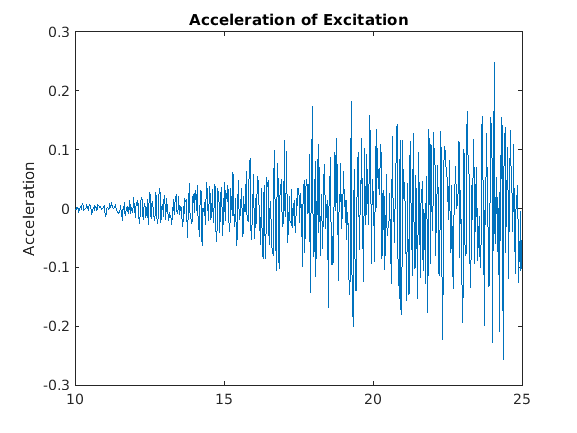

figure
subplot(1,1,1)
plot(t(indexOfInterest),y(indexOfInterest))
ylabel('Acceleration')
title('Acceleration of Excitation')

**Calculate Velocity and Position**

To identify the speed of propagation of the shockwave, we integrate the accelerations once. We use cumulative sums along the time variable to get the velocity of the wave front.

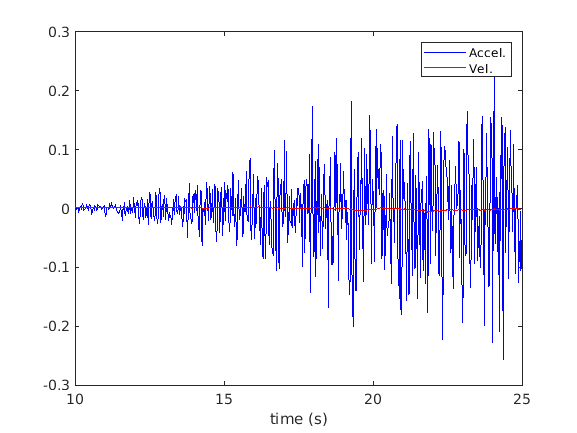

edot = (1/200)*cumsum(y(indexOfInterest));
edot = edot - mean(edot);
figure; plot(t(indexOfInterest), y(indexOfInterest), 'b-', t(indexOfInterest), edot, 'r-')
legend('Accel.', 'Vel.')
xlabel('time (s)')

#### Simulation Function:

function [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn)
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn) generate one time series
% corresponding to acceleration record from a seismometer. The function
% requires 7 inputs, and gives 2 outputs. The time series is generated in
% two steps: First a stationnary process is created based on the Kanai-
% Tajimi spectrum, then an envelope function is used to transform this 
% stationnary time series into a non-stationary record. For more
% information, see [1-3].
% [1] Lin, Y. K., & Yong, Y. (1987). Evolutionary Kanai-Tajimi earthquake
% models. Journal of engineering mechanics, 113(8), 1119-1137.
% [2] Rofooei, F. R., Mobarake, A., & Ahmadi, G. (2001). 
% Generation of artificial earthquake records with a nonstationary 
% KanaiTajimi model. Engineering Structures, 23(7), 827-837.
% [3] Guo, Y., & Kareem, A. (2016). 
% System identification through nonstationary data using TimeFrequency Blind
% Source Separation. Journal of Sound and Vibration, 371, 110-131.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: standard deviation of the excitation.
% fn: [1 x 1 ]: dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]:  bandwidth of the earthquake excitation.
% f: [ 1 x M ]: frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: value at 90 percent of the duration.
% eps: [1 x 1 ]: normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : Simulated aceleration record
% t: size: [ 1 x N ] : time
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.9;
% fn =5;
% T90 = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn);
% figure
% plot(t,y);axis tight
% xlabel('time(s)');
% ylabel('ground acceleration (m/s^2)')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also fitKT.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% Initialisation
w = 2*pi.*f;
fs = f(end); dt = 1/fs;
f0= median(diff(f));
Nfreq = numel(f);
t = 0:dt:dt*(Nfreq-1);

%% Generation of the spectrum S
fn = fn *2*pi; % transformation in rad;
s0 = 2*zeta*sigma.^2./(pi.*fn.*(4*zeta.^2+1));
A = fn.^4+(2*zeta*fn*w).^2;
B = (fn.^2-w.^2).^2+(2*zeta*fn.*w).^2;
S = s0.*A./B; % single sided PSD


%% Time series generation - Monte Carlo simulation
A = sqrt(2.*S.*f0);
B =cos(w'*t + 2*pi.*repmat(rand(Nfreq,1),[1,Nfreq]));
x = A*B; % stationary process

%% Envelop function E
b = -eps.*log(T90)./(1+eps.*(log(T90)-1));
c = b./eps;
a = (exp(1)./eps).^b;
E = a.*(t./tn).^b.*exp(-c.*t./tn);

%% Envelop multiplied with stationary process to get y
y = x.*E;

end